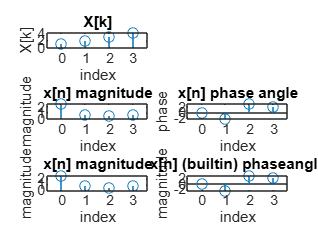

X=input("Enter X[k]:");
N=length(X);
x=zeros(1,N);
for n=0:N-1
    for k=0:N-1
        x(n+1)=x(n+1)+X(k+1)*exp((2j*pi*n*k)/N);
    end
end 
x=x./N;
x_builtin=ifft(X);
subplot(321)
stem(0:N-1,X)
xlabel("index");
ylabel("X[k]");
title("X[k]");
subplot(323)
stem(0:N-1,abs(x));
xlabel("index");
ylabel("magnitude");
title("x[n] magnitude");
subplot(324)
stem(0:N-1,angle(x));
xlabel("index");
ylabel("phase");
title("x[n] phase angle");
subplot(325)
stem(0:N-1,abs(x_builtin));
xlabel("index");
ylabel("magnitude");
title("x[n] magnitude");
subplot(326)
stem(0:N-1,angle(x_builtin));
xlabel("index");
ylabel("magnitude");
title("x[n] (builtin) phaseangle");